## 1. Modelo real (solución desarrollo exacto)

% Parámetros (ajusta según tu caso)
R2 = 50e3;       % Ohm
a = 100;        % unidades apropiadas
b = 10e3;        % unidades apropiadas
R1 = b;
k = 1.38e-23; % J/K
T = 300;      % Kelvin
IDC = linspace(0, 10, 101) * 1e-6;   % IDC biasing
%IDC = 1e-9
VR2_tmodel_square = zeros(size(IDC));
VR2_tideal_square = zeros(size(IDC));

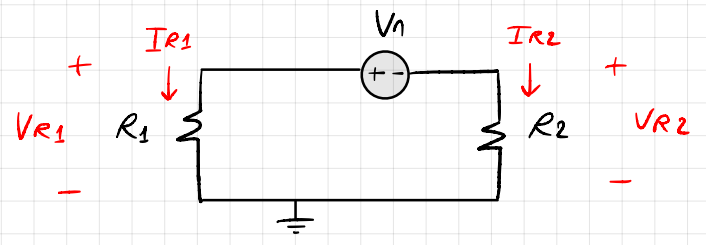

for j = 1:length(IDC)

    % Definir la ecuación V = I^2*a + I*b       I = 0;
    syms I
    eq = I*R2 + I^2*a + I*b - sqrt(4*k*T*(a*IDC(j) + b)) == 0;
    
    % Resolver simbólicamente (solo soluciones reales)
    I_sol = solve(eq, I, 'Real', true);
    
    % Mostrar soluciones
    %disp('Soluciones reales encontradas:');
    %disp(vpa(I_sol, 10));  % mostrar con más precisión
    % Verificar cada solución
    f = @(I) I*R2 + I.^2*a + I*b - sqrt(4*k*T*(a*I + b));
    
    for i = 1:length(I_sol)
        I_val = double(I_sol(i));
        residual = f(I_val);
        %fprintf('I = %.6e A --> f(I) = %.3e\n', I_val, residual);
    end
    %
    VR2_ideal = R2*I_val;

## 2. Solución con el modelo propuesto

### 2.1. Término debido a vn

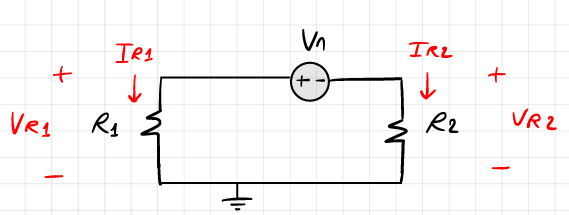

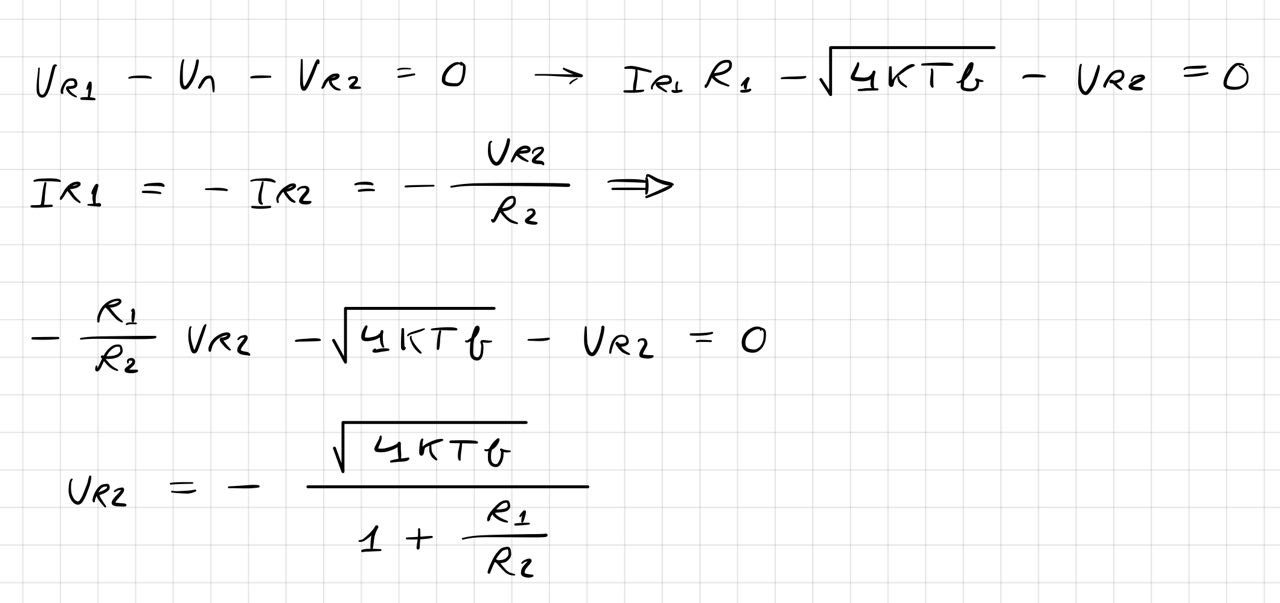

    % Definir la ecuación 
    syms VR2_vn
    VR2_vn_sol = sqrt(4*k*T*b)/(1 + R1/R2);

### 2.2. Término debido a In

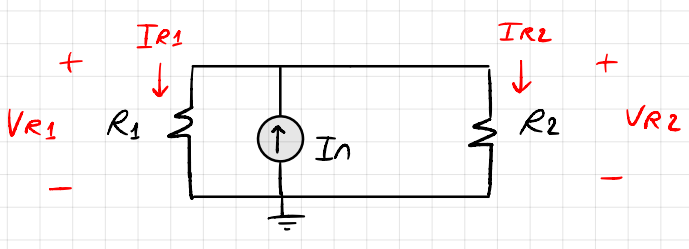

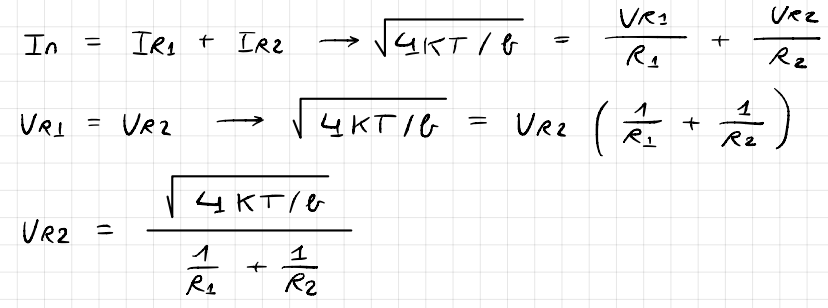

    % Definir la ecuación 
    syms IR1_in
    VR2_in_sol = sqrt(4*k*T/b)/(1/R1 + 1/R2);

### 2.3. Cálculo de la parte real del coeficiente de correlación

    epsilon = 1/2 - (1/(4*b))*2*a*IDC(j);    % duda: uso de IDC?

### 2.4. Comparación

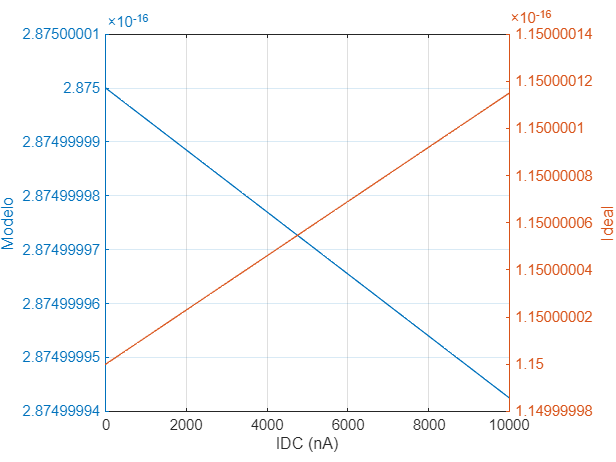

    % IR1_in_vn_sol, VR2_vn_sol, VR2_in_sol
    
    VR2_tmodel_square(j) = VR2_vn_sol^2 + VR2_in_sol^2 + epsilon*VR2_vn_sol*VR2_vn_sol;
    VR2_tideal_square(j) = VR2_ideal^2;
    % comp = VR2_ideal.^2-(VR2_vn_sol(1).^2+VR2_in_sol(1).^2+epsilon*VR2_vn_sol(1)*VR2_in_sol(1))
    % vpa(comp)
end


figure
yyaxis left
plot(IDC * 1e9, VR2_tmodel_square)
ylabel('Modelo')
yyaxis right
plot(IDC * 1e9, VR2_tideal_square)
grid on
ylabel('Ideal')
xlabel('IDC (nA)')